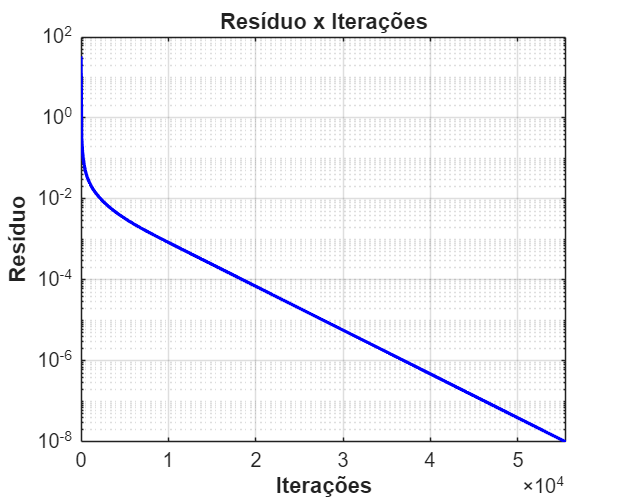

% =========================================================================
% PLOT DOS RESULTADOS DE VALIDAÇÃO - EQUAÇÃO DE LAPLACE
% =========================================================================
clear; clc; close all;

%% 1. GRÁFICO 1: O DECAIMENTO DO RESÍDUO
% Carrega o arquivo do resíduo (segundo passo de tempo)
dados_res = load('norma_iter_laplace.dat');
iteracoes = dados_res(:, 1);
residuo   = dados_res(:, 2);

figure('Name', 'Resíduo de Laplace', 'Color', 'w', 'Position', [100, 100, 500, 400]);
semilogy(iteracoes, residuo, 'b-', 'LineWidth', 2);
grid on;
ax = gca; 
set(ax, 'YMinorGrid', 'on', 'FontSize', 12);
ax.XAxis.Exponent = 4;
xlabel('Iterações', 'FontWeight', 'bold');
ylabel('Resíduo', 'FontWeight', 'bold');
title('Resíduo x Iterações', 'FontWeight', 'bold');
xlim([0 max(iteracoes)]);

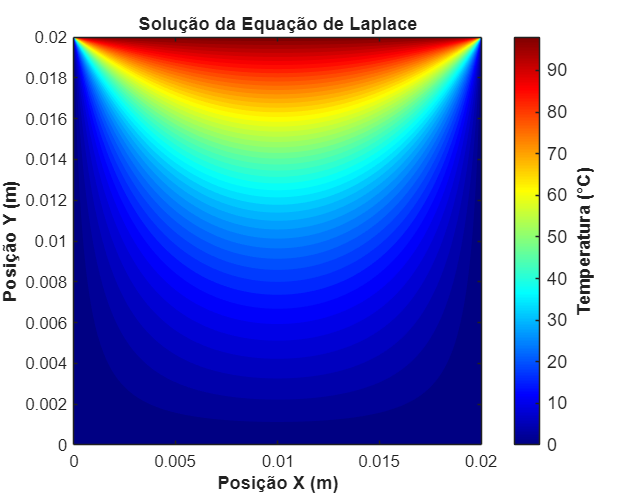

%% 2. GRÁFICO 2: O MAPA DE CALOR )
% Parâmetros da malha
Nx = 200; 
Ny = 200;

% Carrega o mapa de calor
dados_mapa = load('mapa_calor_laplace.dat');
X_vetor = dados_mapa(:, 1);
Y_vetor = dados_mapa(:, 2);
T_vetor = dados_mapa(:, 3);

% Transforma as colunas em matrizes 2D para o plot
X = reshape(X_vetor, [Nx, Ny])';
Y = reshape(Y_vetor, [Nx, Ny])';
T = reshape(T_vetor, [Nx, Ny])';

figure('Name', 'Mapa de Calor - Laplace', 'Color', 'w', 'Position', [650, 100, 500, 400]);
contourf(X, Y, T, 50, 'LineColor', 'none'); % 50 níveis de cores sem linhas pretas
colormap('jet');
c = colorbar;
c.Label.String = 'Temperatura (°C)';
c.Label.FontWeight = 'bold';
c.FontSize = 11;

% Rótulos ajustados com as unidades de medida para o PDF
xlabel('Posição X (m)', 'FontWeight', 'bold');
ylabel('Posição Y (m)', 'FontWeight', 'bold');
title('Solução da Equação de Laplace', 'FontWeight', 'bold');
axis equal;
axis tight;